Author: Michal Szabo              Date: 27.10.2021

# Lab. 1 - Continuous Optimization

******Run this whole file 2 times to see all solutions*****

## Exercise 1

Two mobile robots follow the closed paths described by the equations:

$2x^2 +y^4 +6\textrm{xy}=55$ and ${\left(x-1\right)}^2 +{\left(y^2 -5\right)}^2 -\textrm{xy}=40$

Determine the two critical positions, one per each trajectory, that have the minimum distance between them. 

Solve the problem using function fmincon() of MATLAB and draw the two curves and the segment of minimal length connecting these two curves. 

From the figure, it seems that there exists two more pairs of critical points. Determine them and calculate the distances between all three pairs (for this, change the starting point).

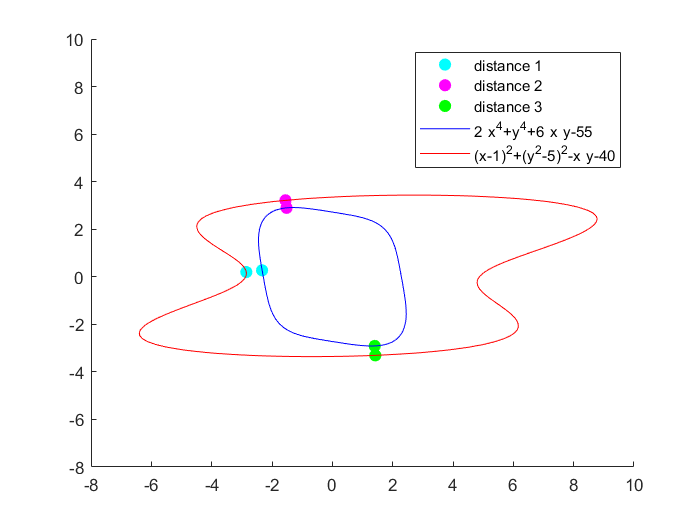

clc; clear

f=@(x) (x(1)-x(3))^2+(x(2)-x(4))^2; 

%    [ x1, y1, x2, y2]
x0 = [ -4, -2,  2,  2;
       -3,  0,  2,  4;
        0, -6,  4, -2];

opts = optimoptions('fmincon','display','none');
for i=1:size(x0,1)
    [x(i,:), fval] = fmincon(f,x0(i,:),[],[],[],[],[],[],@confun,opts);
    dist(i) = sqrt((x(i,1)-x(i,3))^2+(x(i,2)-x(i,4))^2);
end

% Plotting points and curves
figure
hold on
plot(x(1,1),x(1,2),'c.','MarkerSize', 25)
plot(x(1,3),x(1,4),'c.','MarkerSize', 25)
plot(x(2,1),x(2,2),'m.','MarkerSize', 25)
plot(x(2,3),x(2,4),'m.','MarkerSize', 25)
plot(x(3,1),x(3,2),'g.','MarkerSize', 25)
plot(x(3,3),x(3,4),'g.','MarkerSize', 25)
legend('distance 1','','distance 2','','distance 3','')
f1 = @(x,y) 2*x^4+y^4+6*x*y-55;
fimplicit(f1,[-8 10],'b')
warning('off')
f2 = @(x,y) (x-1)^2+(y^2-5)^2-x*y-40;
fimplicit(f2,[-8 10],'r')
warning('off')
hold off

% Printing distances for three closest locations
distances = [1 2 3;
             dist]

distances =     1.0000    2.0000    3.0000
    0.5272    0.3164    0.3955


% Calculating minimal distance
mindist = min(dist);
mindnum = find(dist == mindist);
coordinates = [x(mindnum,1) x(mindnum,2);
               x(mindnum,3) x(mindnum,4)]

coordinates =    -1.5166    2.9009
   -1.5538    3.2151



fprintf(['Minimal distance between closest points is ' ...
         'distance %0.0f and it is %0.4f\n'],mindnum, mindist)

Minimal distance between closest points is distance 2 and it is 0.3164


## Exercise 2

A flour company has three factories or supply points (𝑖=1,2,3) and must deliver their product to five customers or demand points (𝑗=1,2,3,4,5). The production capacity at each factory is 50 tons per day. The demand at each customer is 38, 27, 25, 42 and 18 tons per day respectively. Finally, the transportation cost in € per ton of flour is detailed in the following table: 

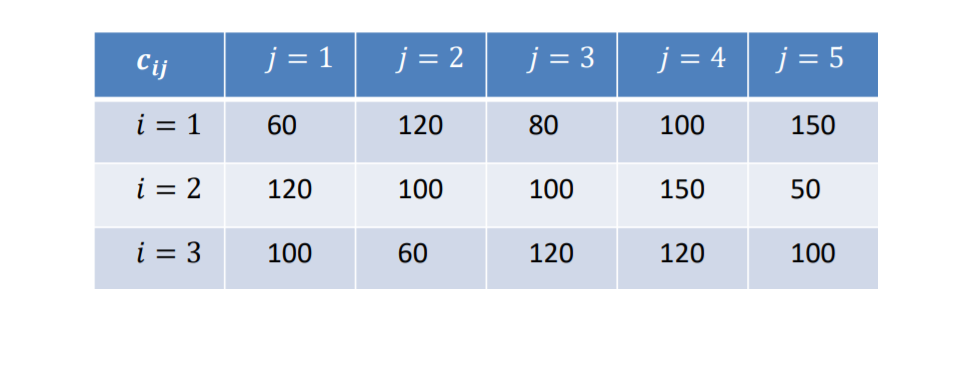

im = imread("images\ex2pic.png"); figure; imshow(im)

Obtain the number of tons of flour to be transported for each supply center to each demand center that minimize the total cost.

clear

S=[50 50 50];
D=[38 27 25 42 18];
C=[ 60 120  80 100 150;
   120 100 100 150  50;
   100  60 120 120 100];

f=reshape(C',1,15);

Aeq1=[1 1 1 1 1 0 0 0 0 0 0 0 0 0 0;
      0 0 0 0 0 1 1 1 1 1 0 0 0 0 0;
      0 0 0 0 0 0 0 0 0 0 1 1 1 1 1];
Aeq2=[1 0 0 0 0 1 0 0 0 0 1 0 0 0 0;
      0 1 0 0 0 0 1 0 0 0 0 1 0 0 0;
      0 0 1 0 0 0 0 1 0 0 0 0 1 0 0;
      0 0 0 1 0 0 0 0 1 0 0 0 0 1 0;
      0 0 0 0 1 0 0 0 0 1 0 0 0 0 1];

Aeq=[Aeq1;Aeq2];
beq=[S,D];
lb=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];

[x,fval,exitflag] = linprog(f,[],[],Aeq,beq,lb);

Optimal solution found.




result = reshape(x,5,3)'

result =     38     0     0    12     0
     0     0    25     7    18
     0    27     0    23     0


## Exercise 3

Consider a robot arm whose base is fixed to the work floor. The arm has to pick up items at various points and place them at other points. What would be a good position for the base of the arm? This would be somewhere “in the middle” of the points it must be able to reach. More precisely, a good position is at the center of the smallest disc that encloses all the points. This point minimizes the maximum distance between the base of the arm and any point it has to reach. We arrive at the following problem: given a set 𝑃 of 𝑛 points in the plane (the points on the work floor that the arm must be able to reach), find the smallest enclosing disc for 𝑃, that is, the smallest disc that contains all the points of 𝑃.


$$\begin{array}{l}
p_1 =\left(0,0\right),{\;p}_2 =\left(3,0\right),p_3 =\left(2,-1\right),p_4 =\left(2,3\right),p_5 =\left(3,4\right),p_6 =\left(4,1\right),\\
p_7 =\left(2,0\right),p_8 =\left(-3,1\right),p_9 =\left(-1,-2\right),p_{10} =\left(1,1\right),p_{11} =\left(4,2\right),p_{12} =\left(1,-1\right),\;
\end{array}$$


Which is this maximum distance between the base robot and a point (length of the arm of the robot)?

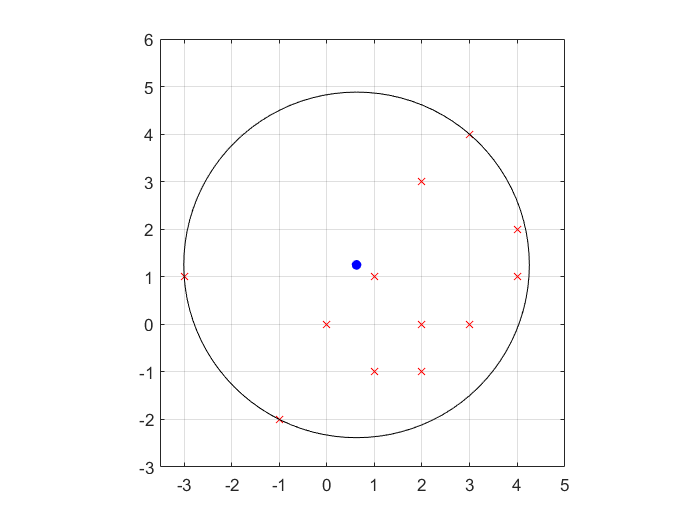

clear

n=12;

Q=[0 0; 3 0; 2 -1; 2 3; 3 4; 4 1; 2 0; -3 1; -1 -2; 1 1; 4 2; 1 -1]'; % Matrix of points

% plotting points 
figure
plot(Q(1,:),Q(2,:),'rx')
axis([-3.5,5,-3,6])
grid on

H=2*(Q'*Q); % Hessian
f=[0 -9 -5 -13 -25 -17 -4 -10 -5 -2 -20 -2]; % Diagonal of the Hessian/-2
Aeq=[1 1 1 1 1 1 1 1 1 1 1 1];  % Linear equality constraints
beq=1;                         
lb=[0 0 0 0 0 0 0 0 0 0 0 0];  % lower bound
opts = optimoptions('fsolve','DiffMinChange',1e-3,'display','none');
[X,FVAL,EXITFLAG] = quadprog(H,f,[],[],Aeq,beq,lb,[],[],opts);

center = Q*X;   % Base coordinates of the circle

% Calculating radius of the circle from 3 furthest points (Should be the same)
r =[];
for i=1:3
    MP = Q(:,X==max(X));  % Finding the furthest point from the base
    r(i) = sqrt((MP(1)-center(1))^2+(MP(2)-center(2))^2);  % Radius
    X(X==max(X)) = 0;
end 
r = max(r);  % Getting largest radius

% plotting circle
d = r*2; px = center(1)-r; py = center(2)-r;
hold on
h = rectangle('Position',[px py d d],'Curvature',[1,1]);
daspect([1,1,1])
plot(center(1),center(2),'b.','MarkerSize', 20)
hold off

fprintf("Position of the base should be at x=%0.4f and y=%0.4f\n", center(1),center(2))

Position of the base should be at x=0.6250 and y=1.2500


fprintf("Maximum distance or radius is r=%0.4f\n", r)

Maximum distance or radius is r=3.6336


## Exercise 4

The problem of finding how electrons optimally distribute themselves on the sphere is a well-known and difficult problem. It is known as Thomson’s problem, and dates from 1904. Thomson’s problem is of interest not just to mathematicians, but also to physicists, chemists and engineers. Here is a mathematical formulation. Let $P$ be a collection of n distinct point $p_1 ,\;\ldotp \ldotp \ldotp ,\;p_m$ from a unit sphere. Let $E$ be the total energy function: 


$$E\left(P\right)=\sum_{i>j} \frac{1}{{\left\lbrack \textrm{dist}\left(p_i ,p_j \right)\right\rbrack }^{\epsilon } }$$


With $\textrm{dist}\left(p_i ,p_j \right)$ is the distance between $p_i$and $p_j$ and $\epsilon \in \left(0,+\infty \right)$. The case$\epsilon \in 1$ is especially interesting to physicists. It is known as the Coulomb potential. When energy is measured with respect to the Coulomb potential, the points are naturally considered to be electrons.

clear

N=4;
x0=[];
for i=1:N
    a=0.5*rand(1);b=0.5*rand(1);c=sqrt(1-a^2-b^2);
    x0=[x0,a,b,c];
end

opts = optimoptions('fmincon','display','none');
[x,fval] = fmincon(@(x)f(x,N),x0,[],[],[],[],[],[],@(x)confun1(x,N),opts);

P=[];
for i=0:(N-1)
    P=[P;[x(3*i+1),x(3*i+2),x(3*i+3)]];
end

M = zeros(N);
for i=1:N
    for j=1:N
        M(i,j)=sqrt((P(i,:)-P(j,:))*(P(i,:)-P(j,:))');
    end
end

% Displaying distances between electrons in matrix M
fprintf('Matrix of distances between electrons')

Matrix of distances between electrons

Distances = M

Distances =          0    1.6330    1.6330    1.6330
    1.6330         0    1.6330    1.6330
    1.6330    1.6330         0    1.6330
    1.6330    1.6330    1.6330         0


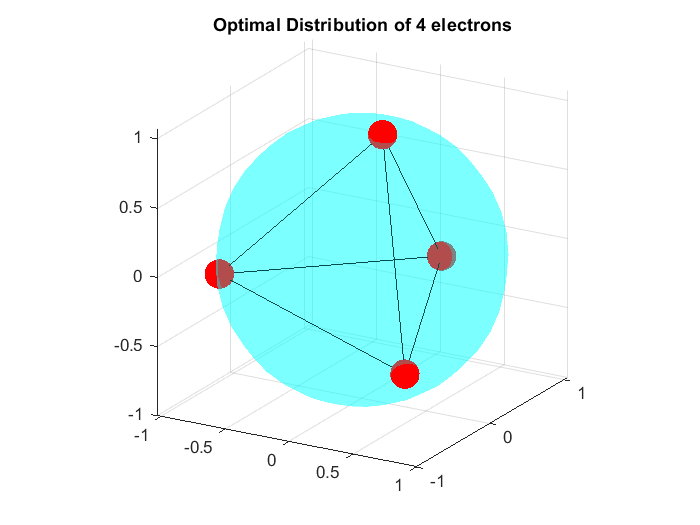


% Ploting sphere
figure
[X,Y,Z] = sphere;  % Initializing sphere coordinates
r_sphere = sqrt(P(1,1)^2+P(1,2)^2+P(1,3)^2);  % Sphere radius
%   [x y z]
a = [0 0 0];
s1 = surf(X*r_sphere+a(1),Y*r_sphere+a(2),Z*r_sphere+a(3), ...
    'FaceColor','c', ...
    'FaceAlpha',0.3, ...
    'EdgeColor','none');
hold on
axis equal
% Ploting electrons
r = 0.1; % electron radius
for i=1:N
    se(i)=surf(X*r+P(i,1),Y*r+P(i,2),Z*r+P(i,3),'FaceColor','r','EdgeColor','none');
end
daspect([1 1 1])
view(30,20)

% Ploting conections between electrons
x=P(:,1);
y=P(:,2);
z=P(:,3);
DT = delaunayTriangulation(x,y,z);
tetramesh(DT,'FaceColor','none')
title(['Optimal Distribution of ', num2str(N), ' electrons'])
hold off

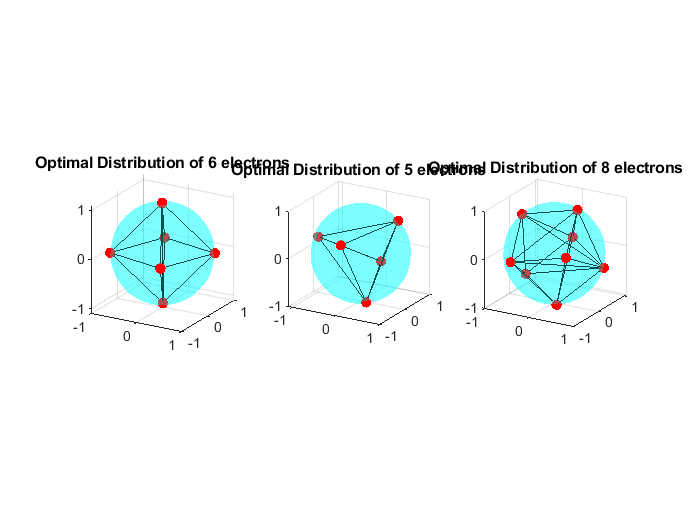


% Finding optimal distribution of N electrons with my function eoptdis(N)
figure
subplot(1,3,1), eoptdis(6);
subplot(1,3,2), eoptdis(5);
subplot(1,3,3), eoptdis(8);

## Exercise 5

We have programed a simple code for minimizing a function using 3 algorithms: 

- Gradient descent with step proportional to the gradient. 

- Steepest descent using second order approximation.

- Newton method.

These algorithms are programed in function minim(). The code needs other functions: 

- objective function that can be defined as an anonymous function: (for instance,$\;f=@\left(x\right)\;{x\left(1\right)}^2 +3{x\left(2\right)}^2$)

- gradf(f,x,Dx): calculate the gradient of function f at point x using increments Dx (central version: 4 points).

- hesf(f,x,Dx): calculate the hessian of function f at point x using increments Dx (9 points).

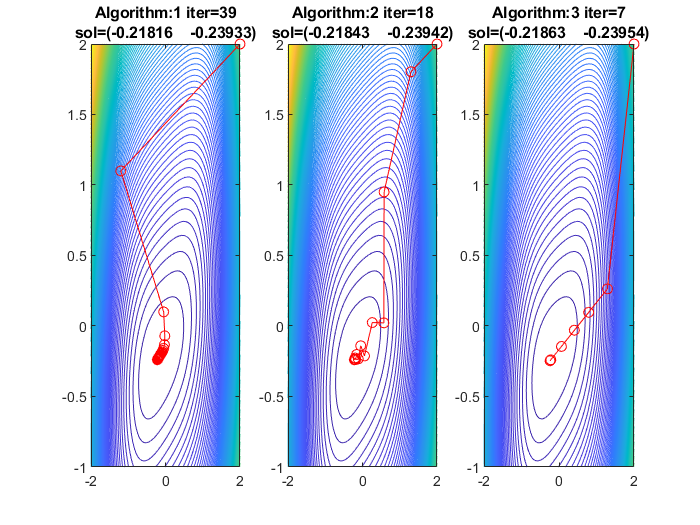

f=@(x) x(1)^4+3*x(2)^2+x(1)^2-2*x(1)*x(2)+x(2);

x=linspace(-2,2,101);
y=linspace(-1,2,101);
[X,Y]=meshgrid(x,y);

Z=zeros(101,101);
for i=1:101
    for j=1:101
        Z(i,j)=f([X(i,j),Y(i,j)]);
    end
end
clf

figure
for alg=1:3 % algorithms
[x,histx,ns,val]=minim(f,[2,2],alg,0.001,500,0.1);
subplot(1,3,alg);
contour(X,Y,Z,100);
axis([-2,2,-1,2]);
hold on
plot(histx(1:(ns+1),1),histx(1:(ns+1),2),'-ro')
title({['Algorithm:', num2str(alg), ' iter=', num2str(ns)]
       ['sol=(', num2str(x'),')']});
end